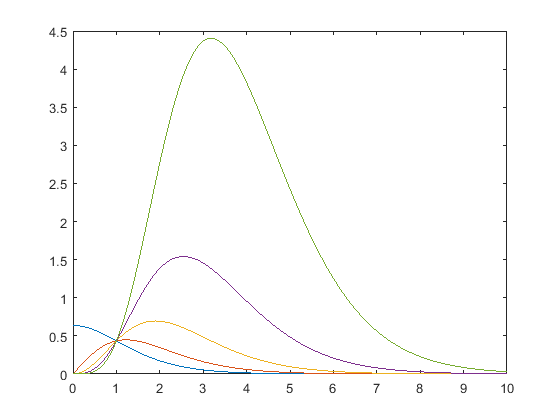

clc; clear; close all;


dxi = 0.01;
xi = dxi:dxi:10;

figure;
for i = 1:5
plot(xi, mu(xi,i));
hold on;
end


n = 1:10;

Mu = zeros(size(i));

for i = 1:length(n)
    Mu(i) = trapz(mu(xi, n(i)))*dxi;
end

function y = mu(xi, n)
y = csch(pi*xi/2).*xi.^n;
end